%Choose object detection probability
P_D = 0.9;
%Choose clutter rate
lambda_c = 10;

%Creat sensor model
range_c = [-1000 1000;-1000 1000];
sensor_model = modelgen.sensormodel(P_D,lambda_c,range_c);
        
%Creat linear motion model
T = 1;
sigma_q = 5;
motion_model = motionmodel.cvmodel(T,sigma_q);
        
%Create linear measurement model
sigma_r = 10;
meas_model = measmodel.cvmeasmodel(sigma_r);
        
%Creat ground truth model
nbirths = 5;
K = 20;
tbirth = zeros(nbirths,1);
tdeath = zeros(nbirths,1);
        
initial_state = repmat(struct('x',[],'P',eye(motion_model.d)),[1,nbirths]);
        
initial_state(1).x = [0; 0; 0; -10];        tbirth(1) = 1;   tdeath(1) = K;
initial_state(2).x = [400; -600; -10; 5];   tbirth(2) = 1;   tdeath(2) = K;
initial_state(3).x = [-800; -200; 20; -5];  tbirth(3) = 1;   tdeath(3) = K;
initial_state(4).x = [0; 0; 7.5; -5];       tbirth(4) = 1;   tdeath(4) = K;
initial_state(5).x = [-200; 800; -3; -15];  tbirth(5) = 1;   tdeath(5) = K;

%% Generate true object data (noisy or noiseless) and measurement data
ground_truth = modelgen.groundtruth(nbirths,[initial_state.x],tbirth,tdeath,K);
ifnoisy = 0;
objectdata = objectdatagen(ground_truth,motion_model,ifnoisy);
measdata = measdatagen(objectdata,sensor_model,meas_model);

%% N-object tracker parameter setting
P_G = 0.999;            %gating size in percentage
w_min = 1e-3;           %hypothesis pruning threshold
merging_threshold = 2;  %hypothesis merging threshold
M = 100;                %maximum number of hypotheses kept in MHT
density_class_handle = feval(@GaussianDensity);    %density class handle
tracker = n_objectracker();
tracker = tracker.initialize(density_class_handle,P_G,meas_model.d,w_min,merging_threshold,M);

TOMHTestimates = TOMHT(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);

z_k =    14.7386  375.4426 -780.2000   22.4392 -208.9279 -861.4247  827.2530  917.9108 -130.6622  959.6193  939.6552 -631.5901  896.1845
    0.4015 -594.8261 -204.1513    0.6393  781.3729  -68.0939   15.3163 -332.2189 -499.5678  140.4994 -163.3558 -467.3653 -865.6868


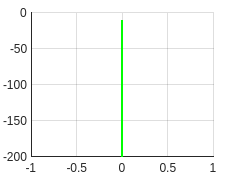

Index in position 1 exceeds array bounds.

Error in tomht_test>@(x)x(1,i) (line 57)
    h4 = plot(cell2mat(cellfun(@(x) x(1,i), TOMHTestimates, 'UniformOutput', false)), ...


figure
hold on
grid on

for i = 1:nbirths
    h1 = plot(cell2mat(cellfun(@(x) x(1,i), objectdata.X, 'UniformOutput', false)), ...
        cell2mat(cellfun(@(x) x(2,i), objectdata.X, 'UniformOutput', false)), 'g', 'Linewidth', 2);
    h4 = plot(cell2mat(cellfun(@(x) x(1,i), TOMHTestimates, 'UniformOutput', false)), ...
        cell2mat(cellfun(@(x) x(2,i), TOMHTestimates, 'UniformOutput', false)), 'b-d', 'Linewidth', 1);
end


xlabel('x'); ylabel('y')

xlim([-1000 1000])
ylim([-1000 1000])